# Pendulum

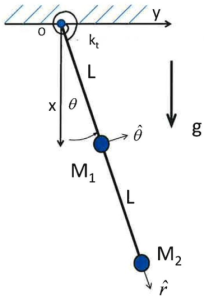

Formulate the second-order equation of motion as a system of two first-order equations by introducing a new variable for angular velocity, $\omega(t) = \dot{\theta}(t)$.

The state vector is


$$\: \mathbf{x}(t) = \left\{ \matrix{\theta(t) \cr \omega(t) } \right\}$$


(We can define this with the variables in any order.)


$$ \left\{ \matrix{\dot{\theta}(t) \cr \dot{\omega}(t) } \right\} = 
\left\{ \matrix{ \omega \cr \frac{-1}{5 m L^2} (k_t \, \theta + 3 m g L \sin{\theta}}\right\}$$


function dxdt = p_rate(t, xx)
    m = 0.36; % kg
    kt = 0.89; % Nm/rad
    L = 0.21; % m
    g = 9.81; % m/s^2
    dxdt = [ xx(2);
        -1/(5*m*L^2)*(kt*xx(1) + 3*m*g*L*sin(xx(1)))];
end

Test

p_rate(0, [1 0])

ans =          0
  -34.7971


Estimate response with linearized, small angle approximation

omega_n = sqrt((kt+3*m*g*L)/(5*m*L^2))

omega_n = 6.2642

period = 2*pi/omega_n

period = 1.0030

tspan = [0, 4*period];

ode45 solution for non-linear dynamics

x0 = [0.1 0];
[tt, X] = ode45(@p_rate, tspan, x0);
figure;
clf;
plot(tt,X(:,1),'LineWidth',2)
xlabel("Time (s)")
ylabel("\theta (rad)")
grid('on')

Overlay linear, small angle approximation.

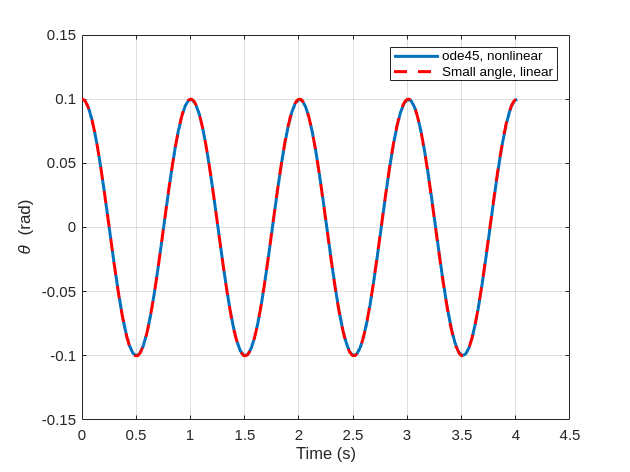

ttt = linspace(tspan(1), tspan(2), 1000);
yyy = x0(1)*cos(omega_n*ttt);
hold on
plot(ttt, yyy, 'r--','LineWidth',2)
legend('ode45, nonlinear', 'Small angle, linear')

Looks pretty close!

Change the initial conditions to a larger initial displacement, say 1.0 radians,

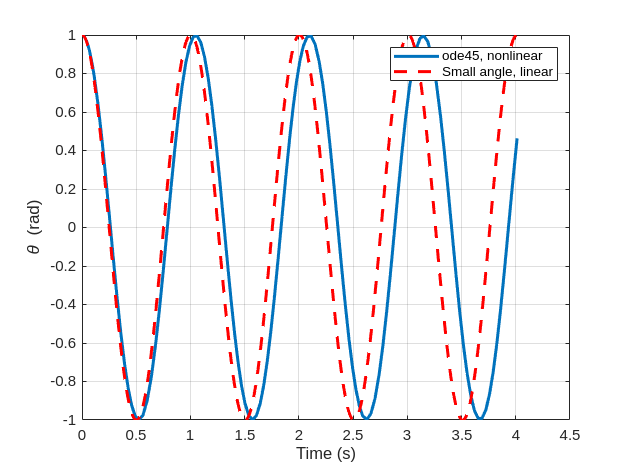

x0 = [1 0];
[tt, X] = ode45(@p_rate, tspan, x0);
figure;
clf;
plot(tt,X(:,1),'LineWidth',2)
xlabel("Time (s)")
ylabel("\theta (rad)")
grid('on')
% overlay linearized approx
yyy = x0(1)*cos(omega_n*ttt);
hold on
plot(ttt, yyy, 'r--','LineWidth',2)
legend('ode45, nonlinear', 'Small angle, linear')

## Extra bits

Below are some additional bits I experimented with in developing the problem.  This can all be safely ignored.

### Parameterizing the function definition using an anonymous function.

function dxdt = p_rate_parameterized(t, xx, m, kt, L, g)
    dxdt = [ xx(2);
        -1/(5*m*L^2)*(kt*xx(1) + 3*m*g*L*sin(xx(1)))];
end

m = 0.36; % kg
kt = 0.89; % Nm/rad
L = 0.21; % m
g = 9.81;
odefunhandle = @(t,xx) p_rate_parameterized(t, xx, m, kt, L, g);

options = odeset('Stats','on');
[tt, X] = ode45(odefunhandle, tspan, x0, options);

35 successful steps
0 failed attempts
211 function evaluations


### Using the Euler solver from the previous assignment

Requires adapting the Euler solver to deal with vectors and matrices - and increasing the number of interation (smaller time step)

[tt2, X2] = euler(odefunhandle, tspan, x0);

figure;
clf;
plot(tt,X(:,1))
size(X)

ans =    141     2


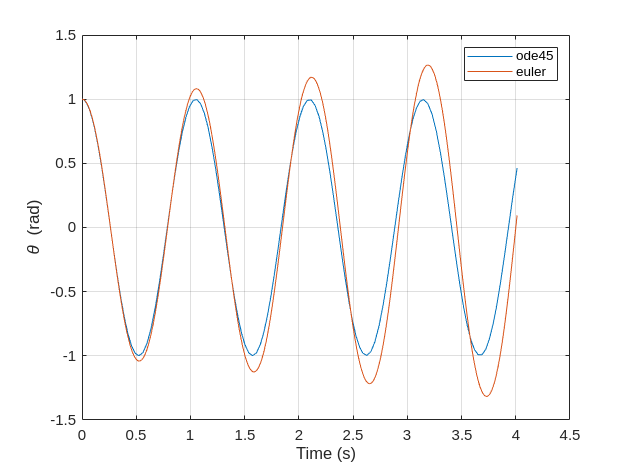

hold on
plot(tt2,X2(:,1))
xlabel("Time (s)")
ylabel("\theta (rad)")
grid('on')
legend('ode45', 'euler')